Set the training image folder, the data should have folders with names the same as the labels....

trainingFolder = 'C:\Users\rickf\Google Drive\Greenstand\SVM\Training';

imds = imageDatastore(trainingFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

imdsAug = augmentedImageDatastore([277,277],imds,'OutputSizeMode','centercrop' );

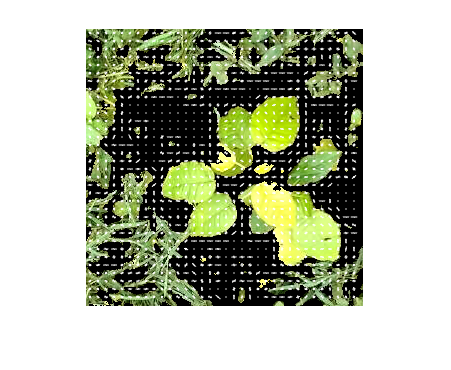

dataTable = readByIndex(imdsAug,20);
img = dataTable{1,1}{1};
img = SegmentGreenWithOtsu(img);

[hog_NxN, plotNxN] = extractHOGFeatures(img,'CellSize',[8,8]);

imshow(img);
hold on;
% Visualize the HOG features

plot(plotNxN);


hogFeatures = zeros(length(imds.Files),length(hog_NxN));


numImages = length(imds.Files);

for i = 1:numImages
    try
        path = imds.Files{i,1};
        dataTable = readByIndex(imdsAug,i);
        img = dataTable{1,1}{1};
        
        img = SegmentGreenWithOtsu(img);
        [features , ~] = extractHOGFeatures(img,'CellSize', [8,8]);
        hogFeatures(i,:) = features;
    catch ME
        disp(ME);
    end
end

  MException with properties:

    identifier: 'nnet_cnn:augmentedImageDatastore:invalidCropOutputSize'
       message: 'When 'OutputSizeMode' in augmentedImageDatastore is 'centercrop', requested 'OutputSize' must be smaller than input image size.'
         cause: {0×1 cell}
         stack: [12×1 struct]

  MException with properties:

    identifier: 'nnet_cnn:augmentedImageDatastore:invalidCropOutputSize'
       message: 'When 'OutputSizeMode' in augmentedImageDatastore is 'centercrop', requested 'OutputSize' must be smaller than input image size.'
         cause: {0×1 cell}
         stack: [12×1 struct]

  MException with properties:

    identifier: 'nnet_cnn:augmentedImageDatastore:invalidCropOutputSize'
       message: 'When 'OutputSizeMode' in augmentedImageDatastore is 'centercro

trainingLabels = imds.Labels;

save('trainingHoGData.mat','hogFeatures','trainingLabels','-v7.3');

        
        